F=@(M) M - M.';
N=3; A=sym('a',N,'real')

$$A = \left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)$$

FA=F(A)

$$FA = \left(\begin{array}{ccc} 0 & a_{1,2}-a_{2,1} & a_{1,3}-a_{3,1}\\ a_{2,1}-a_{1,2} & 0 & a_{2,3}-a_{3,2}\\ a_{3,1}-a_{1,3} & a_{3,2}-a_{2,3} & 0 \end{array}\right)$$

all(isAlways(FA==-FA'))

ans = 1×3 logical array
   1   1   1


tri=tril(FA)

$$tri = \left(\begin{array}{ccc} 0 & 0 & 0\\ a_{2,1}-a_{1,2} & 0 & 0\\ a_{3,1}-a_{1,3} & a_{3,2}-a_{2,3} & 0 \end{array}\right)$$

S=solve(tril(FA),'ReturnConditions',true)

S = struct with fields:
          a1_2: x
          a1_3: y
          a2_1: x
          a2_3: u
          a3_1: y
          a3_2: u
    parameters: [u    x    y]
    conditions: in(u, 'real') & in(x, 'real') & in(y, 'real')


B = [0 S.a1_2 S.a1_3; S.a2_1 0 S.a2_3; S.a3_1 S.a3_2 0]

$$B = \left(\begin{array}{ccc} 0 & x & y\\ x & 0 & u\\ y & u & 0 \end{array}\right)$$


%Compute kernel
S2=solve(FA==0)

S2 = struct with fields:
    a1_2: 0
    a1_3: 0
    a2_1: 0
    a2_3: 0
    a3_1: 0
    a3_2: 0


C=[0 S2.a1_2 S2.a1_3; S2.a2_1 0 S2.a2_3; S2.a3_1 S2.a3_2 0]

$$C = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$


equations = FA == 0;
solution = solve(equations, A)

solution = struct with fields:
    a1_1: 0
    a2_1: 0
    a3_1: 0
    a1_2: 0
    a2_2: 0
    a3_2: 0
    a1_3: 0
    a2_3: 0
    a3_3: 0



%Compute range
%Antisymmetric matrix
equation= (A'==-A);
solve(equation)

ans = struct with fields:
    a1_1: 0
    a1_2: 0
    a1_3: 0
    a2_1: 0
    a2_2: 0
    a2_3: 0
    a3_1: 0
    a3_2: 0
    a3_3: 0


equation= (FA==-FA');
solve(equation)

ans = struct with fields:
    a1_2: 0
    a1_3: 0
    a2_1: 0
    a2_3: 0
    a3_1: 0
    a3_2: 0


all(isAlways(-FA==FA'))

ans = 1×3 logical array
   1   1   1


%all(isAlways(-A==A'))

%Another way:
colspace(FA)

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -\frac{a_{2,3}-a_{3,2}}{a_{1,2}-a_{2,1}} & \frac{a_{1,3}-a_{3,1}}{a_{1,2}-a_{2,1}} \end{array}\right)$$

null(FA)

$$ans = \left(\begin{array}{c} \frac{a_{2,3}-a_{3,2}}{a_{1,2}-a_{2,1}}\\ -\frac{a_{1,3}-a_{3,1}}{a_{1,2}-a_{2,1}}\\ 1 \end{array}\right)$$

A=sym([1 3; 2 6; 0 0;])

$$A = \left(\begin{array}{cc} 1 & 3\\ 2 & 6\\ 0 & 0 \end{array}\right)$$

S=rref(A);
RAT=colspace(A')

$$RAT = \left(\begin{array}{c} 1\\ 3 \end{array}\right)$$

NA=null(A)

$$NA = \left(\begin{array}{c} -3\\ 1 \end{array}\right)$$

RA=colspace(A)

$$RA = \left(\begin{array}{c} 1\\ 2\\ 0 \end{array}\right)$$

NAT=null(A')

$$NAT = \left(\begin{array}{cc} -2 & 0\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

syms a real; 
y=a*RA

$$y = \left(\begin{array}{c} a\\ 2\,a\\ 0 \end{array}\right)$$

xp=A\y

$$xp = \left(\begin{array}{c} a\\ 0 \end{array}\right)$$

B=[RAT NA]

$$B = \left(\begin{array}{cc} 1 & -3\\ 3 & 1 \end{array}\right)$$

coef=B\xp

$$coef = \left(\begin{array}{c} \frac{a}{10}\\ -\frac{3\,a}{10} \end{array}\right)$$

xr=RAT*coef(1)

$$xr = \left(\begin{array}{c} \frac{a}{10}\\ \frac{3\,a}{10} \end{array}\right)$$


$$t_A : x \in \mathbb R^3 \rightarrow y = t_A(x) = Ax \in \mathbb R^2$$


F=@(A,x)A*x;
A=sym([1 2 0; 0 1 1])

$$A = \left(\begin{array}{ccc} 1 & 2 & 0\\ 0 & 1 & 1 \end{array}\right)$$

S=rref(A)

$$S = \left(\begin{array}{ccc} 1 & 0 & -2\\ 0 & 1 & 1 \end{array}\right)$$

RA=colspace(A)

$$RA = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

syms a b real;
x=[a b]

$$x = \left(\begin{array}{cc} a & b \end{array}\right)$$

Ripeti il codice di sopra per questa matrice

y=a*RA

$$y = \left(\begin{array}{cc} a & 0\\ 0 & a \end{array}\right)$$

xp=A\y

$$xp = \left(\begin{array}{cc} a & -2\,a\\ 0 & a\\ 0 & 0 \end{array}\right)$$

B=[colspace(A') null(A)]

$$B = \left(\begin{array}{ccc} 1 & 0 & 2\\ 0 & 1 & -1\\ -2 & 1 & 1 \end{array}\right)$$

coef=B\xp

$$coef = \left(\begin{array}{cc} \frac{a}{3} & -\frac{a}{3}\\ \frac{a}{3} & \frac{a}{6}\\ \frac{a}{3} & -\frac{5\,a}{6} \end{array}\right)$$

xr=RAT*coef(1)

$$xr = \left(\begin{array}{c} \frac{a}{3}\\ a \end{array}\right)$$

Compute l'algoritmo che vedi sulle slide

disp([A [a b]'])

$$\left(\begin{array}{cccc} 1 & 2 & 0 & a\\ 0 & 1 & 1 & b \end{array}\right)$$

x_r=A'*[a b]' 

$$x\_r = \left(\begin{array}{c} a\\ 2\,a+b\\ b \end{array}\right)$$

y=A*A'*[a b]' %Transformation y=A*x_r by expanding x_r definition

$$y = \left(\begin{array}{c} 5\,a+2\,b\\ 2\,a+2\,b \end{array}\right)$$

y2=A*x_r %Above transformation without recomputing x_r

$$y2 = \left(\begin{array}{c} 5\,a+2\,b\\ 2\,a+2\,b \end{array}\right)$$

inv(A*A')*y %Inverse transformation for obtaining [a b], demonstrate bijectivity

$$ans = \left(\begin{array}{c} a\\ b \end{array}\right)$$

A'*[a b]'% to obtain y by x_r

$$ans = \left(\begin{array}{c} a\\ 2\,a+b\\ b \end{array}\right)$$

Computa la distanza tra due linee parallele

%Distanza tra due punti
syms b real;
a=[2 1]' 

a =      2
     1


r=a*b %Retta

$$r = \left(\begin{array}{c} 2\,b\\ b \end{array}\right)$$

x=[1 3]'

x =      1
     3


Ta=@(a) [a*a'/norm(a)^2]

Ta = function_handle with value:
    @(a)[a*a'/norm(a)^2]


A=Ta(a)

A =     0.8000    0.4000
    0.4000    0.2000


y=A*x

y =     2.0000
    1.0000


[norm(x) norm(y)]

ans =     3.1623    2.2361


ans =     2.2361    2.2361


$$c = \left(\begin{array}{c} 2\,d\\ d \end{array}\right)$$

$$r2 = \left(\begin{array}{c} 2\,d+4\\ d+4 \end{array}\right)$$

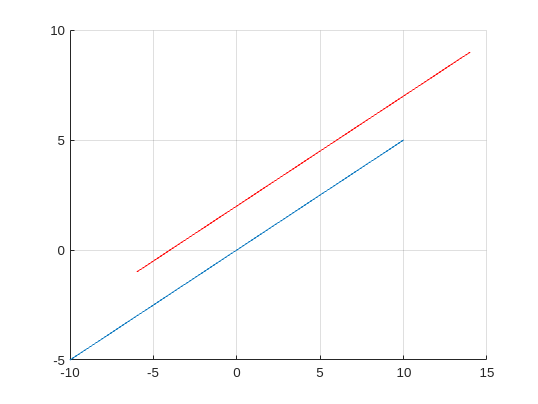

z =     0.8000    0.4000
    0.4000    0.2000


    2.0000    0.8000    0.4000
    1.0000    0.4000    0.2000



[norm(x-y) sqrt(sum((x-y).^2))]

syms lambda real;
a=[2 1]' 

a =      2
     1


a*lambda %this span will be the direction of the line

$$ans = \left(\begin{array}{c} 2\,\lambda \\ \lambda \end{array}\right)$$

p1=[1 3]' %p1

p1 =      1
     3


p2=[4 5]' %p2

p2 =      4
     5


A=a*a'/norm(a)^2 %Projection matrix

A =     0.8000    0.4000
    0.4000    0.2000



L1=p1+lambda*a %Formal define the line 1

$$L1 = \left(\begin{array}{c} 2\,\lambda +1\\ \lambda +3 \end{array}\right)$$

L2=p2+lambda*a %Formal define the line 2

$$L2 = \left(\begin{array}{c} 2\,\lambda +4\\ \lambda +5 \end{array}\right)$$

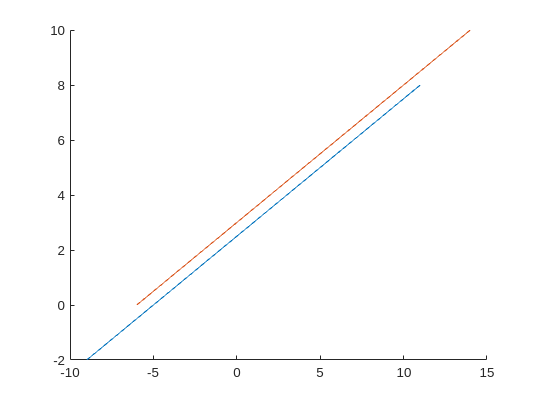

figure; hold on; %Check they're parallel (true)
fplot(L1(1),L1(2));
fplot(L2(1),L2(2));
hold off;


norm(L1)

$$ans = \sqrt{{\left|\lambda +3\right|}^{2}+{\left|2\,\lambda +1\right|}^{2}}$$

norm(L2)

$$ans = \sqrt{{\left|\lambda +5\right|}^{2}+{\left|2\,\lambda +4\right|}^{2}}$$

norm(L1-L2)

$$ans = \sqrt{13}$$

a*(p1-p2)'/norm(a)

ans =    -2.6833   -1.7889
   -1.3416   -0.8944



%ChatGPT Solution
d=(p1-p2)%Distance between the two points

d =     -3
    -2


%Now compute the projection of this d onto the spanned line lambda*a
d_proj=A*d %likewise we did with point on the previous exercise

d_proj =    -3.2000
   -1.6000


norm(d_proj) %The distance is the norm of d_proj

ans = 3.5777


%in short we could write the transformation as:
TA=@(a,p1,p2) norm((a*a'/norm(a)^2)*(p1-p2))

TA = function_handle with value:
    @(a,p1,p2)norm((a*a'/norm(a)^2)*(p1-p2))


TA(a,p1,p2)

ans = 3.5777



yL1= A*p1

yL1 =     2.0000
    1.0000


yL2= A*p2

yL2 =     5.2000
    2.6000


norm(yL1-yL2)

ans = 3.5777

Spiega quali mappe lineari sfruttano queste fattorizzazioni di A:

LU

A=rand(2,2,'double')

A =     0.0527    0.2691
    0.7379    0.4228


[L,U,P]=lu(A)

L =     1.0000         0
    0.0714    1.0000


U =     0.7379    0.4228
         0    0.2389


P =      0     1
     1     0


[S,V,D]=svd(A);
(L*U)

ans =     0.7379    0.4228
    0.0527    0.2691


B1=[1 0; A(2,1)/A(1,1) 1]

B1 =     1.0000         0
   14.0072    1.0000


B2=[1 0; 1 0];
A.*B1

ans =     0.0527         0
   10.3353    0.4228


A-B1

ans =    -0.9473    0.2691
  -13.2694   -0.5772


SVD

% Define the matrix A
[U,S,V]=svd(A)

U =    -0.2184   -0.9759
   -0.9759    0.2184


S =     0.8703         0
         0    0.2026


V =    -0.8406    0.5417
   -0.5417   -0.8406



% Compute A^T A and A A^T
ATA = A' * A

ATA =     0.5472    0.3262
    0.3262    0.2512


AAT = A * A'

AAT =     0.0752    0.1527
    0.1527    0.7232



% Eigenvalue decomposition of A^T A
[eigV, eigS] = eig(ATA)

eigV =     0.5417   -0.8406
   -0.8406   -0.5417


eigS =     0.0410         0
         0    0.7574



% Eigenvalue decomposition of A A^T
[eigU, ~] = eig(AAT)

eigU =    -0.9759    0.2184
    0.2184    0.9759



% Singular values are the square roots of the eigenvalues of A^T A
singularValues = sqrt(diag(eigS))

singularValues =     0.2026
    0.8703



% Construct Sigma matrix
m = size(A, 1);
n = size(A, 2);
Sigma = zeros(m, n);
Sigma(1:length(singularValues), 1:length(singularValues)) = diag(singularValues);

% Construct U and V matrices
U = eigU;
V = eigV;
disp([U Sigma V])

   -0.9759    0.2184    0.2026         0    0.5417   -0.8406
    0.2184    0.9759         0    0.8703   -0.8406   -0.5417



[U,S,V]=svd(A);
disp([U,S,V])

   -0.2184   -0.9759    0.8703         0   -0.8406   -0.5417
   -0.9759    0.2184         0    0.2026    0.5417   -0.8406



Rivoluzione di un solido

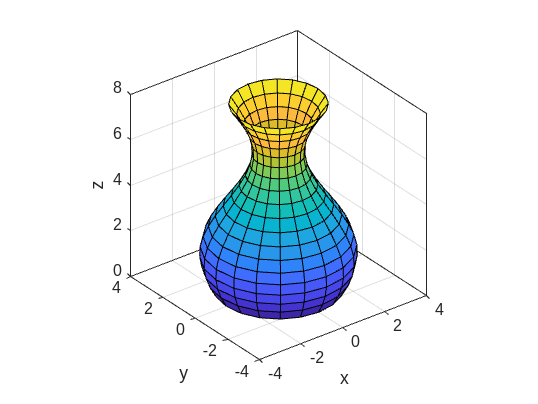

t=(-pi/3:pi/10:2*pi-pi/2)';
y=2+cos(t);
[X,Y,Z]=cylinder(y); Z=8*Z;
figure(1); surf(X,Y,Z); axis equal
box on; hold on
set(gca,'FontSize',12)
AX=[-4 4 -4 4 0 8]; axis(AX)
xlabel('x'); ylabel('y'); zlabel('z')


disp([X,])